# Classification with Machine Learning

First, install the [**Statistics and Machine Learning Toolbox**](https://www.mathworks.com/products/statistics.html).

Then, check out the [**Machine Learning Onramp**](https://www.mathworks.com/learn/tutorials/machine-learning-onramp.html) to learn about machine learning in MATLAB. Afterward, predict whether the tclab data shows that the TCLab is on, or off.

## Summary

Classification with machine learning is through supervised (labeled outcomes), unsupervised (unlabeled outcomes), or with semi-supervised (some labeled outcomes) methods. From the many methods for classification the best one depends on the problem objectives, data characteristics, and data availability. Below is a complete compilation of the source code for supervised and unsupervised learning methods.

## Exercise

Develop a classifier to predict when the [**TCLab heater**](https://apmonitor.com/heat.htm) is on and when it is off. Generate labeled data where the heater is either on at 100% output or at 0% output for periods between 10 and 25 seconds.

*Small Data Set (10 min)*

We test the classifier by splitting the data set into a training and test set. The data is generated from a TCLab or accessed at the link below.

 [**Data for Testing**](https://apmonitor.com/do/uploads/Main/tclab_data5.txt)

## **Generate Small Data**

Load data

test = readtable('https://apmonitor.com/do/uploads/Main/tclab_data5.txt')

test = 601×5 table
    Time    Q1    Q2     T1       T2  
    ____    __    __    _____    _____

      0     0     0        16    16.06
      1     0     0        16    16.06
      2     0     0     15.94    16.06
      3     0     0     16.03    16.06
      4     0     0     16.03    16.06
      5     0     0     16.03    16.06
      6     0     0     16.03    16.06
      7     0     0        16    16.06
      8     0     0     16.06    16.06
      9     0     0     15.94    16.06
     10     0     0     16.06    16.06
     11     0     0     16.03    16.06
     12     0     0     16.03    16.06
     13     0     0     16.03    16.06
     14     0     0     16.06    16.06
     15     0     0     16.03    16.06


Add Derivative feature

test.dT1dt = zeros(length(test.Time),1);
test.d2T1dt2 = zeros(length(test.Time),1);
for i = 2:length(test.Time)
    dt = test.Time(i) - test.Time(i-1); 
    test.dT1dt(i) = (test.T1(i) - test.T1(i-1))/dt;
    test.d2T1dt2(i) = (test.dT1dt(i) - test.dT1dt(i-1))/dt;
end

Rescale to between 0 and 1

test = normalize(test,'range')

test = 601×7 table
      Time       Q1    Q2        T1           T2         dT1dt     d2T1dt2
    _________    __    __    __________    _________    _______    _______

            0    0     0      0.0024546    0.0028986    0.39516    0.35751
    0.0016667    0     0      0.0024546    0.0028986    0.39516    0.35751
    0.0033333    0     0     0.00098184    0.0028986    0.34677    0.32642
        0.005    0     0       0.003191    0.0028986    0.46774    0.43523
    0.0066667    0     0       0.003191    0.0028986    0.39516    0.31088
    0.0083333    0     0       0.003191    0.0028986    0.39516    0.35751
         0.01    0     0       0.003191    0.0028986    0.39516    0.35751
     0.011667    0     0      0.0024546    0.0028986    0.37097    

*Large Data Set (1 hr)*

 [**Data for Training**](https://apmonitor.com/do/uploads/Main/tclab_data6.txt)

## **Generate Large Data**

Load data

train = readtable('https://apmonitor.com/do/uploads/Main/tclab_data6.txt')

train = 3601×5 table
    Time    Q1    Q2     T1       T2  
    ____    __    __    _____    _____

      0     0     0     16.06       16
      1     0     0     16.06    15.97
      2     0     0     16.06    16.03
      3     0     0     16.03       16
      4     0     0     16.03    15.94
      5     0     0     16.06       16
      6     0     0     16.03       16
      7     0     0     16.06    15.94
      8     0     0     16.06    15.97
      9     0     0     16.06    15.97
     10     0     0     16.06    15.94
     11     0     0     16.06    15.97
     12     0     0     16.06    15.97
     13     0     0     16.06    15.94
     14     0     0     16.06    15.94
     15     0     0     16.06    15.94


Add Derivative feature

train.dT1dt = zeros(length(train.Time),1);
train.d2T1dt2 = zeros(length(train.Time),1);
for i = 2:length(train.Time)
    dt = train.Time(i) - train.Time(i-1); 
    train.dT1dt(i) = (train.T1(i) - train.T1(i-1))/dt;
    train.d2T1dt2(i) = (train.dT1dt(i) - train.dT1dt(i-1))/dt;
end

Rescale to between 0 and 1

train = normalize(train,'range')

train = 3601×7 table
       Time       Q1    Q2        T1           T2         dT1dt     d2T1dt2
    __________    __    __    __________    _________    _______    _______

             0    0     0     0.00068244    0.0089686        0.5    0.33333
    0.00027778    0     0     0.00068244     0.006278        0.5    0.33333
    0.00055556    0     0     0.00068244     0.011659        0.5    0.33333
    0.00083333    0     0              0    0.0089686    0.49107    0.32738
     0.0011111    0     0              0    0.0035874        0.5    0.33929
     0.0013889    0     0     0.00068244    0.0089686    0.50893    0.33929
     0.0016667    0     0              0    0.0089686    0.49107    0.32143
     0.0019444    0     0     0.00068244    0.0035874   

Select and scale (0-1) the features of the data such as temperature, and temperature derivatives. Use the measured temperature and derivatives and heater value labels to create a classifier that predicts when the heater is on or off. Validate the classifier with new data that was not used for training.

## **Solution**

- Run the below code to open the classification Learner

- Select New Session from Workspace 

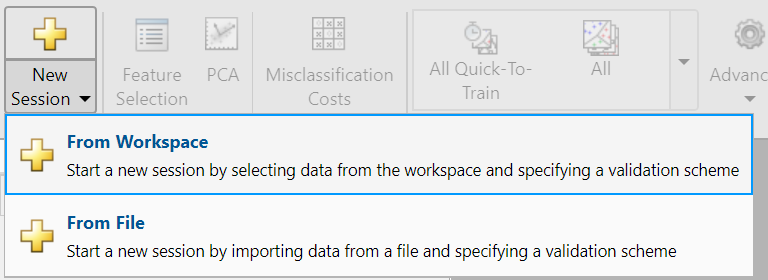

        3. Select the train data set, Q1 as the response variable, and the other features as predictors which will be used to predict whether the heater is on.

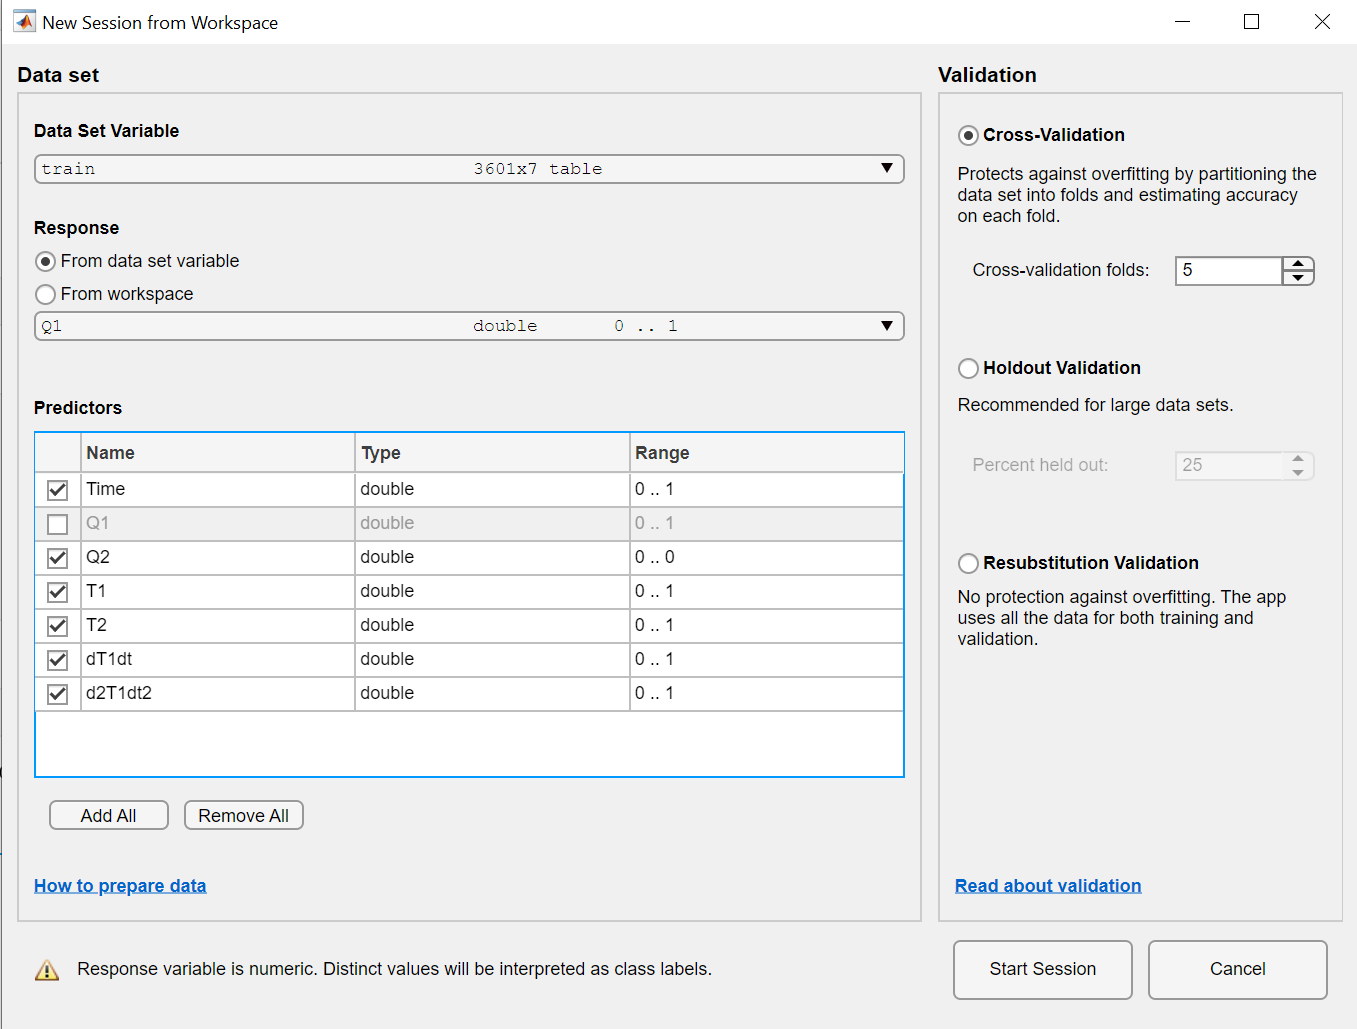

        4. Click Start Session

        5. Within the Classification Learner app, select  All Quick-To-Train in the model type menu

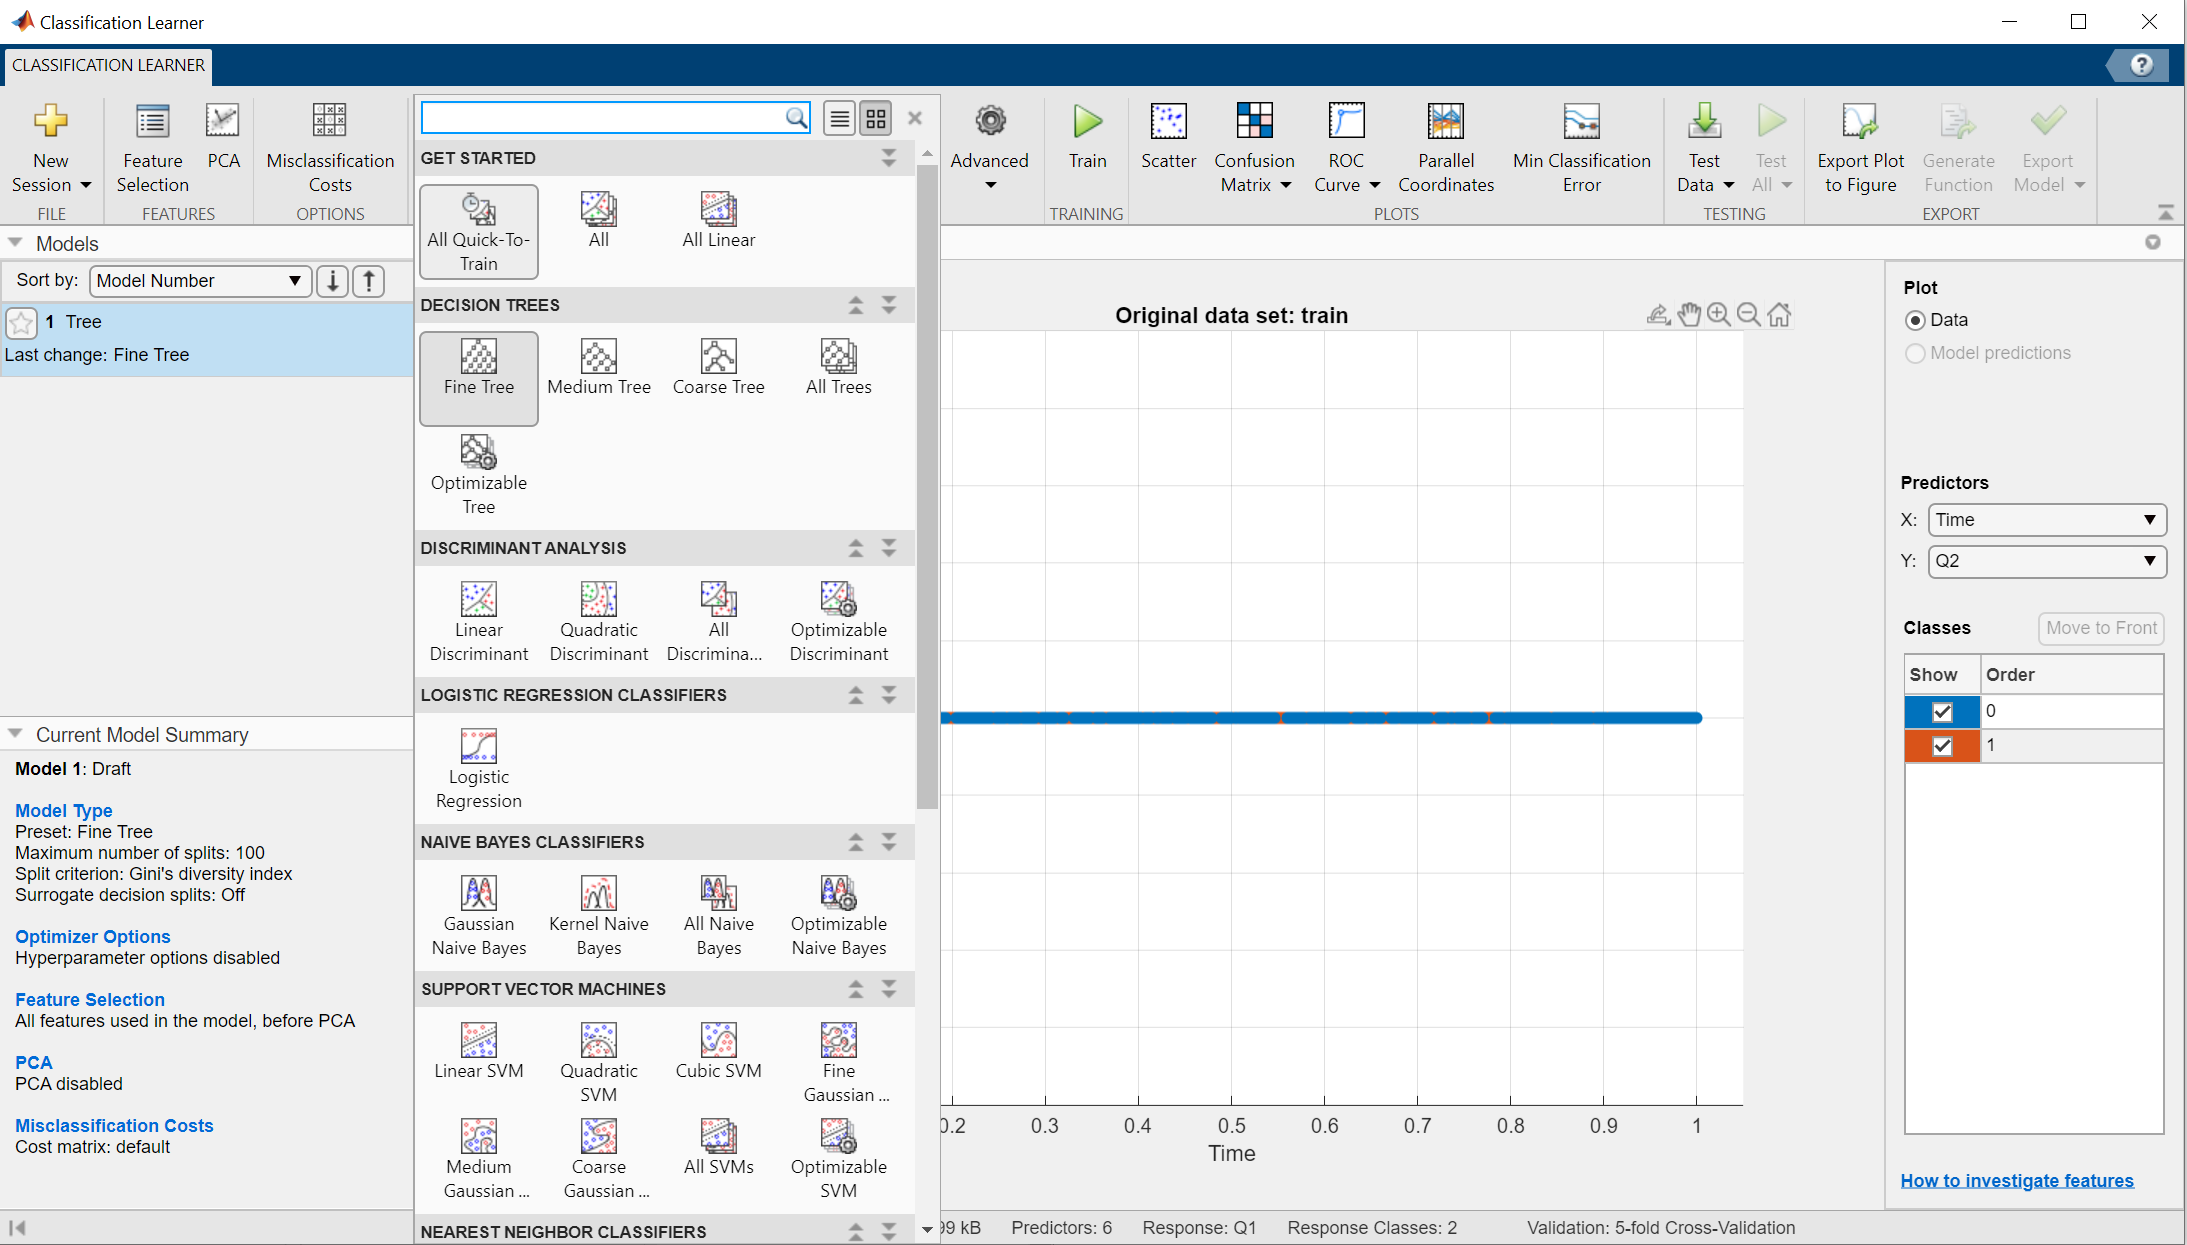

        6. Train the models and compare the accuracies and trends of different models using the provided graph

classificationLearner